# Code for the FFT of the force measurement

clear all;clc;
%Read the required Excel file

## ___Reading the excel file and smoothing_____

A = xlsread('MotionDataWorkable.csv');
[noOfData,forceAxis] = size(A);

fprintf('The excel has %d rows and %d column\n',noOfData,forceAxis);

The excel has 152400 rows and 6 column


## ___Ask for user input_____

prompt = {'Enter window size for moving average:',...
    'Enter column for FFT:',...
             'Enter frequency of data acquisition:',...
             'Enter row location for starting point for FFT',...
             'Enter row location for ending point for FFT'};
         dlgtitle = 'Input';
         dims = [1 35];
         definput = {'20','2','1000','10000','10000'};
answer = inputdlg(prompt,dlgtitle,dims,definput);

## ___Gather information from user input_____

window = str2double(answer{1});
columnForFFT = str2double(answer{2});
acquisitionFrequency = str2double(answer{3});
startPoint = str2double(answer{4});
endPoint = str2double(answer{5});

## ___Data smoothing_____

A = smoothdata(A(2:noOfData,:),'movmedian',window);

## ___FFT preparation_____

Fs = acquisitionFrequency;                                       % Sampling frequency
T = 1/Fs;                                           % Sampling period
L = noOfData-2;                                           % Length of signal
t = (0:L-1)*T;                                      % Time vector
Fn = Fs/2;                                          % Nyquist Frequency
% FX = fft(X)/L  ;                                    % Fourier Transform
Fv = linspace(0, 1, fix(L/2)+1)*Fn ;                % Frequency Vector
Iv = 1:length(Fv);                                  % Index Vector

## ___FFT_____

FXdcoc = fft(A(startPoint:noOfData-endPoint,columnForFFT)-mean(A(startPoint:noOfData-endPoint,columnForFFT)))/L;

## ___Post processing_____

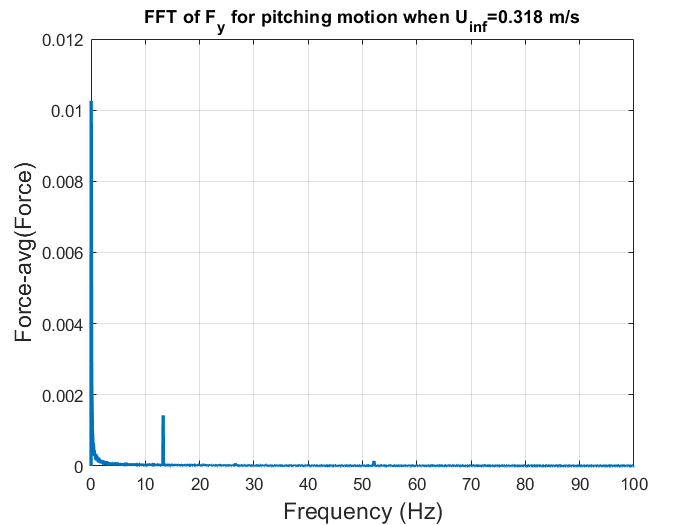

ffvv = transpose(Fv);
fxdcoc = abs(FXdcoc(Iv))*2;

figure
plot(Fv, abs(FXdcoc(Iv))*2,'LineWidth',2)
 xlim([0 100])
grid
title('FFT of F_{y} for pitching motion when U_{inf}=0.318 m/s')
xlabel('Frequency (Hz)','fontsize',14)
ylabel('Force-avg(Force)','fontsize',14)